%addpath 'C:\Users\anonf\OneDrive\uni\phys project\matlab\iwave\development\matlab'

load_parameters

t_end = 0.0336

f_a_original = 4.8356e+08

axion_linewidth = 483.5590

axion_Q = 1000000

f_a = 2.4178e+07

%% generate axion frequency
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);

%plot(t, f_axion)
%yline([f_a - axion_linewidth/2, f_a + axion_linewidth/2])

%% generate signal and noise
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
noise_power = calculate_noise_power(f_sampling, T)

noise_power = 1.5843e-17

noise = generate_thermal_noise(t, f_sampling, noise_power);

x = signal + noise;
%x = noise;
%x = signal;

f_0 = f_a - 7e3

f_0 = 2.4171e+07

Q = 1e4;
y = resonator(x, f_0, f_0*ones(size(x)), Q, f_sampling);

num_chunks = 2;

% test for length
[f, pwr] = do_fft(y(1:chunk_length), f_sampling);

[f, pwr] = do_fft(y, f_sampling);

bin_width = f(2) - f(1)

bin_width = 476.8372

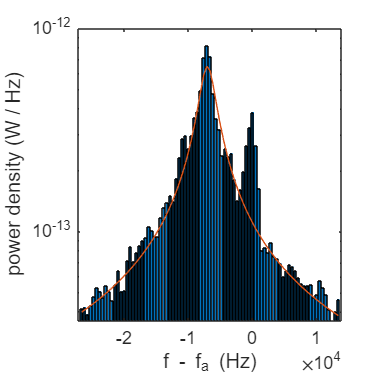

disp_width = 1e5;
start_index = find(f > f_0 - 0.2e5, 1);
end_index = find(f > f_0 + 0.2e5, 1);
%end_index = length(f)-1;
%start_index = find(f > f_0 - disp_width, 1);
%end_index = find(f > f_0 + disp_width, 1);
chop = start_index : end_index;

powers = pwr;

f_ = f(chop);
p_ = powers(chop);

figure
adstyle(8, 8)
%bar(f, pwr)
bar(f_ - f_a, p_)
set(gca, 'yscale','log')
%xline(f_0)
%xline(f_a)
%xline(f_0 * 2 * pi)

omega_0 = 2*pi * f_0;
Delta_0 = omega_0 / f_sampling;
w = Delta_0 / (2 * Q);

Delta = 2*pi*f_/f_sampling;

A_Delta = (1 - exp(-w)) ./ sqrt(1 - 2*exp(-w)*cos(Delta - Delta_0) + exp(-2*w)); % from Ed paper
noise_model = A_Delta * 6.5e-13;
hold on
plot(f_ - f_a, noise_model)
xlabel('f - f_a (Hz)')
ylabel('power density (W / Hz)')


%xline([f_a - axion_linewidth/2, f_a + axion_linewidth/2])
%xline([f_0 - f_0/Q/2, f_0 + f_0/Q/2])

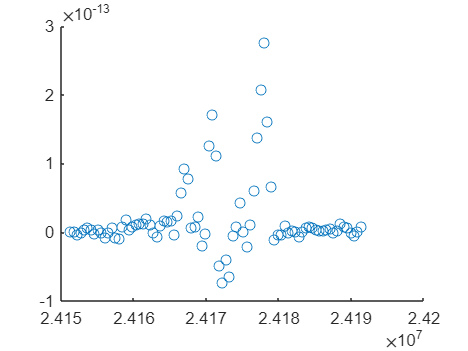

figure
scatter(f_, p_-noise_model)

f_0 = f_sampling/5000;

omega_0 = 2*pi * f_0;
Delta_0 = omega_0 / f_sampling;
Q = 1e4

Q = 10000

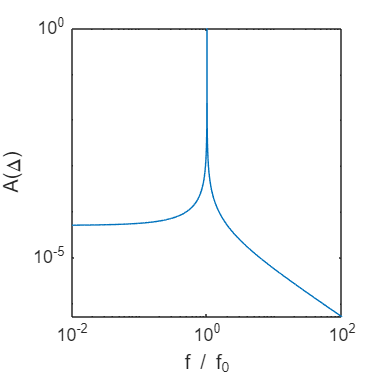

w = Delta_0 / (2 * Q);

f = logspace(-2, 2, 2001);

Delta = 2*pi*(f*f_0)/f_sampling;

A_Delta = (1 - exp(-w)) ./ sqrt(1 - 2*exp(-w)*cos(Delta - Delta_0) + exp(-2*w)); % from Ed paper
figure
adstyle(8, 8)
loglog(f, A_Delta)
ylabel('A(\Delta)')
xlabel('f / f_0')
saveas(gca, 'figures/filter.eps', 'epsc')


%xline([f_a - axion_linewidth/2, f_a + axion_linewidth/2])
%xline([f_0 - f_0/Q/2, f_0 + f_0/Q/2])

function [f, pwr] = do_fft(x, f_sampling)
    [pwr, f] = nsd_pwelch(x, 0.002, f_sampling);
    %figure
    %loglog(f, pwr)
end